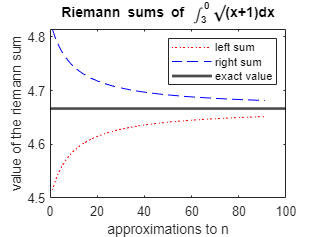

% Exercise 2: Riemann sums
% definite integral: from 0 to 3 of sqrt(x+1) dx
b=3;
a=0;
y=0;
sum_left = zeros(1, 91);
sum_right = zeros(1, 91);
sumleft = 0;
sumright = 0;

for n = 10:100
    deltx = (b-a)/n;
    sumleft = 0;
    sumright = 0;
    for x = 0:deltx:3-deltx
        sumleft = sumleft + sqrt(x+1)*deltx;
    end
    for x = deltx:deltx:3
        sumright = sumright + sqrt(x+1)*deltx;
    end
    sum_left(1,n-9)=sumleft;
    sum_right(1,n-9)=sumright;
end
plot(sum_left,'r:')
hold on
plot(sum_right,'b--')
yline(14/3,'k', LineWidth=2)
xlabel("approximations to n")
ylabel("value of the riemann sum")
title("Riemann sums of \int_{3}^{0}\surd(x+1)dx")
legend("left sum","right sum", "exact value")